# Processing Radar Data to Output SNR

### User to Define which range doppler slice to visualise:

k = 29; % define which slice number you want to visalise

### This script will, for input data:

- Uses func slice_SNR to calculate the peak power, the noise (mean of the abs of dthe data), the SNR, and the index of the peak power.  

- Generate a Range-Doppler for the defined slice within the input data.

- Plot a large white diamond marker where the peak power is represented in the Range-Doppler.

- Saves the figure as a .PNG

#### Preperation of data

inputstructure = active; % define your data input structure
inputstructure.name = "Active"; % define your data input name
inputdata = inputstructure.range_doppler_slices;  
signal=zeros(1,length(inputdata));
noise=zeros(1,length(inputdata));
SNR=zeros(1,length(inputdata));
slices_range_doppler = createArrays(length(inputdata), size(inputdata{1,1}));
for i=1:length(inputdata)
    [signal(i),noise(i),SNR(i),slices_range_doppler{i},signal_idx(i)]=slice_SNR(inputdata{1,i});
end    

Define Range-Doppler user input configuration

x = inputstructure.range_axis; % x_axis
y = inputstructure.doppler_velocity_axis; % y_axis
dynamic_range = +50; % user defined dynamic range to maximise visualisation
max_range = 500; % user defined max range to maximise visualisation
max_doppler = 60; % user defined max doppler to maximise visualisation

Generate Range-Doppler image with scaled colours

figure_title = (inputstructure.name + ' Range Doppler Slice ' + k...
    + ' of ' + length(inputdata));
fig = figure;
imagesc(x,y,slices_range_doppler{1, k},[-dynamic_range 0])
title(figure_title);
ylabel('Doppler Velocity [m/s]');
xlabel('Range (m)') ;  
c = colorbar;
c.Label.String='Norm Power [dB]';
ylim([-max_doppler max_doppler]); % Doppler Limit
xlim([-inf max_range]);   % Range Limit
colormap jet;
hold on

Return row and column index positions for peak signal index

[idx_doppler, idx_range] = ind2sub(size(slices_range_doppler{1,k}),signal_idx(k))

idx_doppler = 244

idx_range = 2

Convert index row and column into doppler and range using active. axis

idx_range_axis = inputstructure.range_axis(idx_range)

idx_range_axis = 4.9965

idx_doppler_axis = inputstructure.doppler_axis(idx_doppler)

idx_doppler_axis = -14

Plot peak signal on top of Range-Doppler as large white diamond

plot(idx_range_axis, idx_doppler_axis...
    , "diamondk", "MarkerFaceColor","w",...
    'MarkerSize', 10)
hold off

Save generated image as .PNG

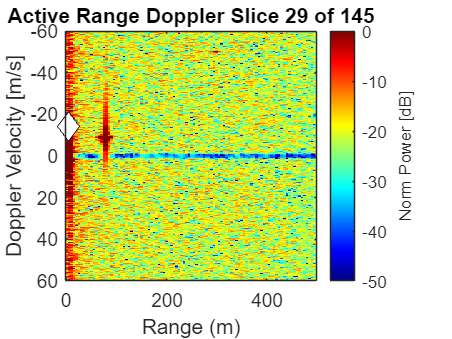

exp_dir = repo_directory + '\bladeRAD-Rikki\figures\experiment_' + experiment_number + '_active' + '\slice_images'; % user defined export directory
fig_name = exp_dir + '\' + figure_title;
savefig(figure_title)
saveas(fig, fig_name, 'png')

## Quantify Signal and Noise

signal; % output from slice_SNR function
noise; % output from slice_SNR function

## Define SNR in dB for all slices

User defined level of noise desired

user_defined_noise = 10  % User defiend noise [dB]

user_defined_noise = 10

Take the input data complex array and apply the awgn function

inputdata_plus_noise = createArrays(length(inputdata),...
    size(inputdata{1,1}));
for i=1:length(inputdata)
    inputdata_plus_noise{1,i} = awgn(inputdata{1,i}, user_defined_noise, 'measured'); % complex + awgn
end

Convert the noise induced complex array to power using the slice_SNR func

signal_plus_noise=zeros(1,length(inputdata));
noise_plus_noise=zeros(1,length(inputdata));
SNR_plus_noise=zeros(1,length(inputdata));
slices_range_doppler_plus_noise = createArrays(length(inputdata), size(inputdata{1,1}));
for i=1:length(inputdata)
    [signal_plus_noise(i),noise_plus_noise(i),SNR_plus_noise(i),...
        slices_range_doppler_plus_noise{i},...
        signal_idx_plus_noise(i)]=slice_SNR(inputdata_plus_noise{1,i});
end  

Apply awgn to Input data after it is convert into power

slices_range_doppler_dB_plus_noise = createArrays(length(inputdata),...
    size(inputdata{1,1}));
for i=1:length(inputdata)
    slices_range_doppler_dB_plus_noise{1,i} = awgn(slices_range_doppler{1,i},...
        user_defined_noise, 'measured'); % dB + awgn
end

Visualise the slice chosen by the user both with & without awgn applied at complex and dB stages

figure_title = (inputstructure.name +...
    ' Range Doppler Slice '...
    + k + ' of ' + length(inputdata));
fig = figure;

subplot(3, 1, 1);
imagesc(x,y,slices_range_doppler{1, k},[-dynamic_range 0])
title(figure_title);
ylabel('Doppler Velocity [m/s]');
xlabel('Range (m)') ;  
c = colorbar;
c.Label.String='Norm Power [dB]';
ylim([-max_doppler max_doppler]); % Doppler Limit
xlim([-inf max_range]);   % Range Limit
colormap jet;

subplot(3, 1, 2);
imagesc(x,y,slices_range_doppler_plus_noise{1, k},[-dynamic_range 0])
title(figure_title + ' +' + user_defined_noise + 'dB Noise at Complex Stage');
ylabel('Doppler Velocity [m/s]');
xlabel('Range (m)') ;  
c = colorbar;
c.Label.String='Norm Power [dB]';
ylim([-max_doppler max_doppler]); % Doppler Limit
xlim([-inf max_range]);   % Range Limit
colormap jet;

subplot(3, 1, 3);
imagesc(x,y,slices_range_doppler_dB_plus_noise{1, k},[-dynamic_range 0])
title(figure_title + ' +' + user_defined_noise + 'dB Noise Post Complex to Power Conversion');
ylabel('Doppler Velocity [m/s]');
xlabel('Range (m)') ;  
c = colorbar;
c.Label.String='Norm Power [dB]';
ylim([-max_doppler max_doppler]); % Doppler Limit
xlim([-inf max_range]);   % Range Limit
colormap jet;

Save figures to repo

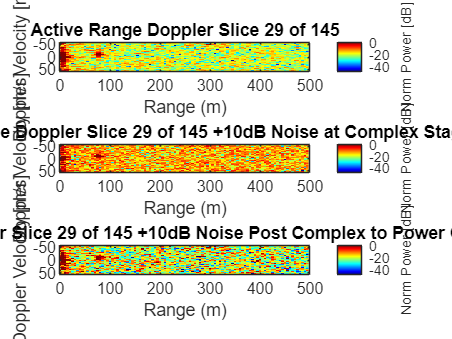

exp_noise = repo_directory + '\bladeRAD-Rikki\figures\experiment_' + experiment_number + '_active' + '\noisy_image_comparison'; % user defined export directory
fig_name = exp_noise + '\' + figure_title;
savefig(inputstructure.name + ' Range Doppler Slice ' + k + length(inputdata))
saveas(fig, fig_name, 'png')

## Plot SNR against Time (?) for all slices of Active data

figure_title = (inputstructure.name + ' SNR for '...
    + length(inputdata) + ' Slices');
fig = figure;
plot(1:length(SNR), SNR, 1:length(SNR_plus_noise), SNR_plus_noise)

title(figure_title);
ylabel('SNR [dB]');
xlabel('Slice No') ;
legend("SNR", 'SNR + Noise')
grid on
%ylim([-max_doppler max_doppler]); % Doppler Limit
xlim([-inf length(SNR)]);   % Range Limit


Save figure to repo

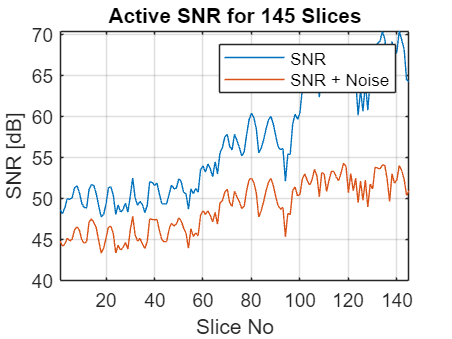

exp_graph = repo_directory + '\bladeRAD-Rikki\figures\experiment_' + experiment_number + '_active' + '\snr_vs_slice'; % user defined export directory
fig_name = exp_graph + '\' + figure_title;
savefig(inputstructure.name + ' SNR for ' + length(inputdata) + ' Slices ')
saveas(fig, fig_name, 'png')

## Inject Noise to the Active Data Using awgn function (+10dB)

% injected_noise_figure = 10 % [dB]
% inputdata_injected_noise = createArrays(length(inputdata), size(inputdata{1,1}));
% for i=1:length(inputdata)
%         [inputdata_injected_noise{i}] = slices_range_doppler{1, i} + injected_noise_figure;
%         % awgn - try on complex pre-func, then apply func to new data set
% end  

Generate Range-Doppler image with scaled colours for Noise Injected Data

% figure_title = (inputstructure.name + ' Range Doppler with '...
%     + injected_noise_figure + 'dB Noise Added - Slice ' + k...
%     + ' of ' + length(inputdata_injected_noise));
% fig = figure;
% imagesc(x,y,inputdata_injected_noise{1, k},[-dynamic_range 0])
% title(figure_title);
% ylabel('Doppler Velocity [m/s]');
% xlabel('Range (m)') ;  
% c = colorbar;
% c.Label.String='Norm Power [dB]';
% ylim([-max_doppler max_doppler]); % Doppler Limit
% xlim([-inf max_range]);   % Range Limit
% colormap jet;
% hold on

Save generated image as .PNG

% exp_dir = exp_dir; % user defined export directory
% fig_name = exp_dir + figure_title;
% savefig(figure_title)
% saveas(fig, fig_name, 'png')